addpath(genpath('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\MATLABrelated\'))
clear all;close all;
load S_letter_path.mat

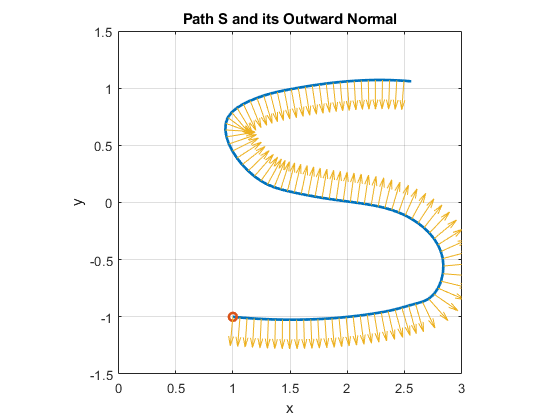

%
% define unit vectors
%
hold off
zz=zeros(3,1); ex = [1;0;0]; ey = [0;1;0]; ez = [0;0;1];
figure(1);plot(Sls(1,:),Sls(2,:),Sls(1,1),Sls(2,1),'o','linewidth',2);
xlabel('x');ylabel('y');
axis([0 3 -1.5 1.5]);axis('square');grid;

% xT and yT of the T link
path_prime = diff(Sls')'./vecnorm(diff(Sls')');
yT = [path_prime; zeros(1,size(path_prime,2))];
xT = -crossmat(ez)*yT;
ax = gca;
hold(ax,'on')
quiver(Sls(1,1:end-1),Sls(2,1:end-1),xT(1,:),xT(2,:));
title('Path S and its Outward Normal')

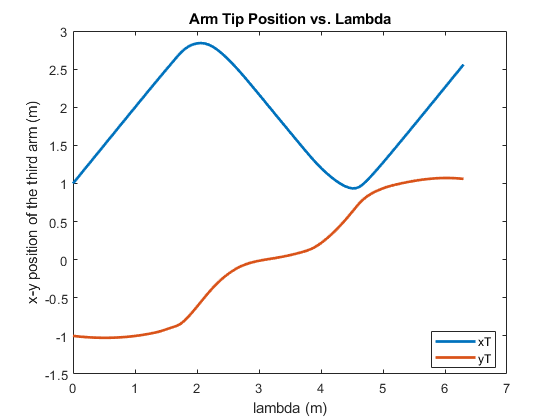

% generate path length array
l = [0, cumsum(vecnorm(diff(Sls')'))];
figure(2);
plot(l,Sls,'linewidth',2)
title('Arm Tip Position vs. Lambda')
legend('xT','yT','Location',"best")
xlabel('lambda (m)')
ylabel('x-y position of the third arm (m)')

% Forward kinematics
syms q1 q2 q3 l1 l2 l3
p01 = sym([0;0]);r01 = rot2(q1);
p12 = [l1;0];r12 = rot2(q2);
p23 = [l2;0];r23 = rot2(q3);
p3T = [l3;0];r3T = sym(rot2(0));
p0T = simplify(p01 + r01*p12 + r01*r12*p23 + r01*r12*r23*p3T)

$$p0T = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

r03 = simplify(r01*r12*r23)

$$r03 = \left(\begin{array}{cc} \cos\left(q_{1}+q_{2}+q_{3}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$


% Inverse Kinematics with algebra
syms xt yt qt
eq1 = qt == q1 + q2 + q3;
p0T = subs(p0T, rhs(eq1),lhs(eq1))

$$p0T = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(\mathrm{qt}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(\mathrm{qt}\right) \end{array}\right)$$

eq2_a = xt-l3*cos(qt) == l2*cos(q1+q2) + l1*cos(q1)

$$eq2\_a = \mathrm{xt}-l_{3}\,\cos\left(\mathrm{qt}\right)=l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)$$

eq2_b = yt-l3*sin(qt) == l2*sin(q1+q2) + l1*sin(q1)

$$eq2\_b = \mathrm{yt}-l_{3}\,\sin\left(\mathrm{qt}\right)=l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)$$

eq3 = lhs(eq2_a)^2+lhs(eq2_b)^2 == rhs(eq2_a)^2 + rhs(eq2_b)^2

$$eq3 = {\left(\mathrm{xt}-l_{3}\,\cos\left(\mathrm{qt}\right)\right)}^{2}+{\left(\mathrm{yt}-l_{3}\,\sin\left(\mathrm{qt}\right)\right)}^{2}={\left(l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)}^{2}+{\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)}^{2}$$

eq3 = simplify(eq3)

$$eq3 = {l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}={\left(\mathrm{xt}-l_{3}\,\cos\left(\mathrm{qt}\right)\right)}^{2}+{\left(\mathrm{yt}-l_{3}\,\sin\left(\mathrm{qt}\right)\right)}^{2}$$

eq3 = isolate(eq3,cos(q2))

$$eq3 = \cos\left(q_{2}\right)=-\frac{{l_{1}}^{2}+{l_{2}}^{2}-{\left(\mathrm{xt}-l_{3}\,\cos\left(\mathrm{qt}\right)\right)}^{2}-{\left(\mathrm{yt}-l_{3}\,\sin\left(\mathrm{qt}\right)\right)}^{2}}{2\,l_{1}\,l_{2}}$$

% Inverse Kinematics with Geometric 
p13 = [xt;yt] -p01 - rot2(qt)*p3T

$$p13 = \left(\begin{array}{c} \mathrm{xt}-l_{3}\,\cos\left(\mathrm{qt}\right)\\ \mathrm{yt}-l_{3}\,\sin\left(\mathrm{qt}\right) \end{array}\right)$$

d = norm(p13)

$$d = \sqrt{{\left|\mathrm{xt}-l_{3}\,\cos\left(\mathrm{qt}\right)\right|}^{2}+{\left|\mathrm{yt}-l_{3}\,\sin\left(\mathrm{qt}\right)\right|}^{2}}$$


%q=subprob3(k,p1,p2,d)

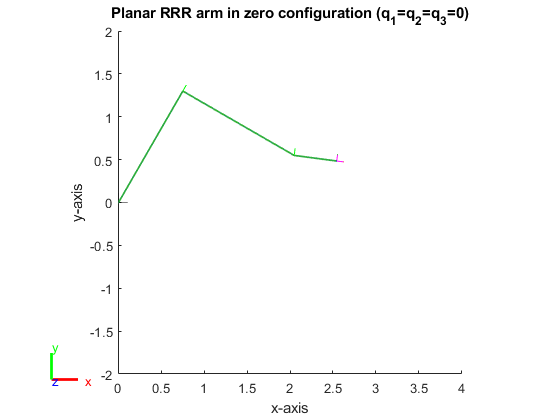

% robot parameters
l1 = 1.5; l2 = 1.5; l3 = 0.5;
%l1 = 1.5; l2 = 1.5; l3 = 0.1;
%l1 = 2; l2 = 1.5; l3 = 0.25;
%l1 = 1.5; l2 = 1.5; l3 = 1;
robot.P = [zz l1*ex l2*ex l3*ex];
robot.H = [ez ez ez];
robot.joint_type=[0 0 0];

% zero configuration 
robot.q=[pi/3;-pi/2;pi/8];
% radius of the link (as cylinders)
radius = .01;
robot_rb=defineRobot(robot,radius);
figure(10);hold on;show(robot_rb,robot.q,'Collision','on');
view(-360.001,90);
axis([0,4,-2,2]);axis('square');
xlabel('x-axis');ylabel('y-axis');
title('Planar RRR arm in zero configuration (q_1=q_2=q_3=0)')
hold off

part 3 

n_link = 3; % 3 links
zz = [0;0;0]; ex=[1;0;0]; ez=[0;0;1];
% first check symbolically
syms q1 q2 q3 real
syms l1 l2 l3 real
robotsym.P = sym([zz l1*ex l2*ex l3*ex]);
robotsym.H = sym([ez ez ez]);
robotsym.q=[q1;q2;q3];
robotsym.joint_type=[0 0 0];
% caculate forward kinematics 
robotsym=nlinkfwdkin(robotsym);
% display final orientation and position
disp('R0T');disp(simplify(robotsym.T(1:2,1:2)));

R0T


$$\left(\begin{array}{cc} \cos\left(q_{1}+q_{2}+q_{3}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

disp('p0T');disp(simplify(robotsym.T(1:2,4)));

p0T


$$\left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

% display Jacobian
%disp('JT');disp(simplify(robotsym.J(1:3,1:3)));
%disp('det(JT)');disp(simplify(det(robotsym.J(1:3,1:3))));

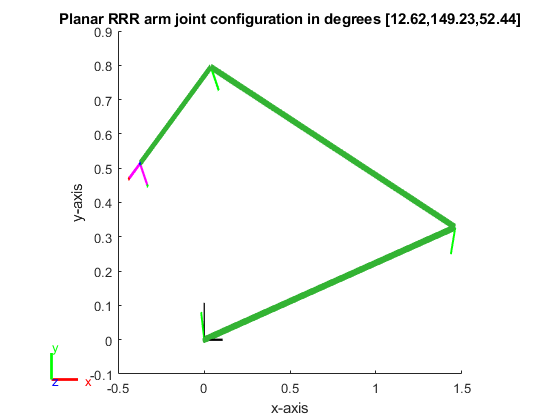

% robot parameters
l1 = 1.5; l2 = 1.5; l3 = 0.5;
%l1 = 1.5; l2 = 1.5; l3 = 0.1;
%l1 = 2; l2 = 1.5; l3 = 0.25;
%l1 = 1.5; l2 = 1.5; l3 = 1;
robot.P = [zz l1*ex l2*ex l3*ex];
robot.H = [ez ez ez];
robot.joint_type=[0 0 0];

% zero configuration 
robot.q=[pi/3;-pi/2;pi/8];
% radius of the link (as cylinders)
radius = .01;
robot_rb=defineRobot(robot,radius);
robot.T = eye(4,4);
%robot.q=zeros(3,1);
robot.q=(rand(3,1)-.5)*2*pi;
figure;
plotarm(robot)

% forward kinematics
robot=nlinkfwdkin(robot);
% inverse kinematics (2 solutions)
%qsol=threelink_invkin_subproblem(robot)
% 
qsol=threelink_invkin_geometric(robot)

qsol =     2.8248    0.2203
   -2.6045    2.6045
   -2.7635    0.9152


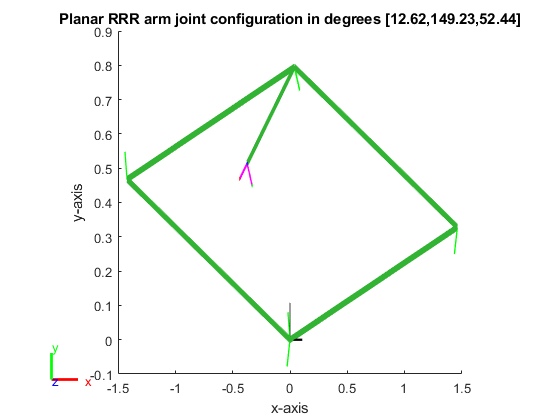

%
figure;
robot.q=qsol(:,1);plotarm(robot);
robot.q=qsol(:,2);plotarm(robot);

%{ 
N=100;alpha=.1;
robot.q=(rand(size(robot.q))-.5)*2*.05;
robot=invkin_iterJ(robot,100,.1);
qsol2=robot.q
%}

Part 4

nl=length(Sls);
qsol1=zeros(3,nl-1);
qsol2=zeros(3,nl-1);
for i=1:nl-1
    robot.T(1:3,1:4)=[xT(:,i) yT(:,i) ez [Sls(:,i);0]];
    qsol=threelink_invkin_geometric(robot);
    qsol1(:,i)=qsol(:,1);
    qsol2(:,i)=qsol(:,2);    
end

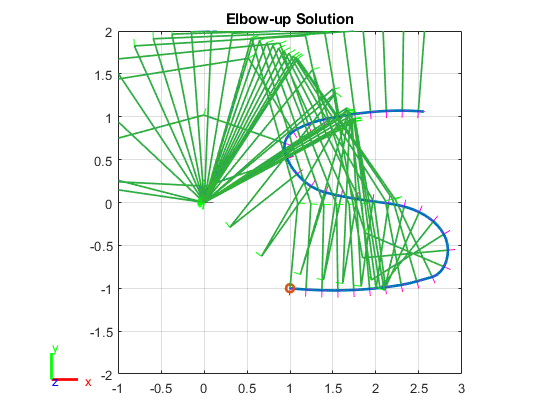

close all
figure(2);plot(Sls(1,:),Sls(2,:),Sls(1,1),Sls(2,1),'o','linewidth',2);
hold on
grid;axis([-1,3,-2,2]);axis('square');
for i=1:3:nl-1
    robot.q=qsol1(:,i);pause(.1);
    show(robot_rb,robot.q,'Collision','on'); 
    view(0,90);
end
title('Elbow-up Solution')
grid on;

fprintf('max joint speed: %5.4f, %5.4f, %5.4f\n',max(abs(diff(qsol1')')')');

max joint speed: 1.4049, 0.1706, 1.5838


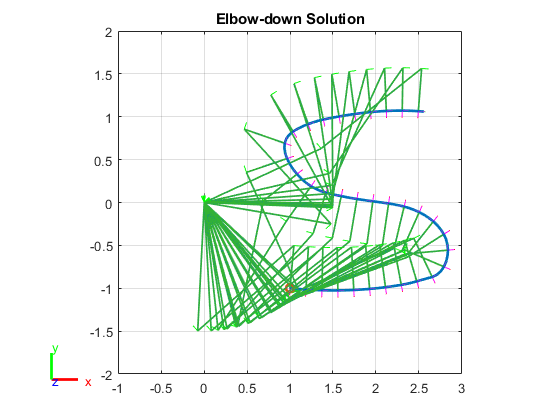

close all
figure(3);plot(Sls(1,:),Sls(2,:),Sls(1,1),Sls(2,1),'o','linewidth',2);
hold on
axis([-1,3,-2,2]);axis('square');
for i=1:3:nl-1
    robot.q=qsol2(:,i);
    show(robot_rb,robot.q,'Collision','on'); 
    view(0,90);
end
title('Elbow-down Solution')
grid on;

fprintf('max joint speed: %5.4f, %5.4f, %5.4f\n',max(abs(diff(qsol2')')')');

max joint speed: 0.2348, 0.2269, 0.3598


Part 5 dqdt = dqdl * dldt -> dldt = dqdt / dqdl

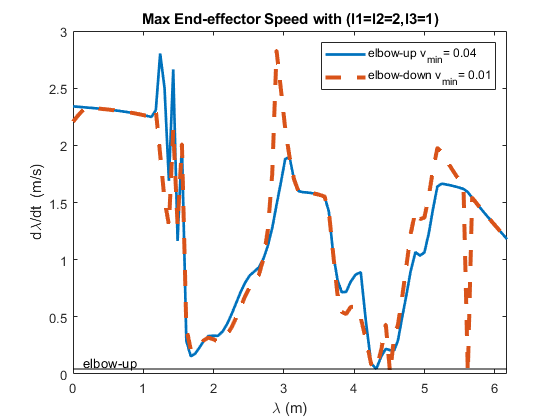

dqdt = 1; %  rad/sec
dqdlmax1 = max(abs(diff(qsol1')./diff(l(1:end-1)'))');
dldt1 = dqdt./dqdlmax1;
dqdlmax2 = max(abs(diff(qsol2')./diff(l(1:end-1)'))');
dldt2 = dqdt./dqdlmax2;

dldtmin1 = min(dldt1);
dldtmin2 = min(dldt2);

figure;plot(l(1:end-2),dldt1,'linewidth',2);
hold on;plot(l(1:end-2),dldt2,'linewidth',3,'LineStyle',"--");
hline(dldtmin1,'k','elbow-up');
hold off
legend(['elbow-up v_{min}= ',num2str(round(dldtmin1,2))],...
      ['elbow-down v_{min}= ',num2str(round(dldtmin2,2))])
xlabel('\lambda (m)')
ylabel('d\lambda/dt  (m/s)')
xlim([0,l(end-2)])
title('Max End-effector Speed with (l1=l2=2,l3=1)')

Part 6

% 
umax=[1;1;1];
%amax=[.05;.05;.05]; %not used

ls = [0, cumsum(vecnorm(diff(Sls')'))];
N=length(ls); % provided ls
qT=zeros(1,N);
pT=zeros(2,N);
qTprime=zeros(1,N);
pTprime=zeros(2,N);
q1=zeros(3,N);
q2=zeros(3,N);

ldot1=zeros(1,N);
ldot2=zeros(1,N);
qdot1=zeros(3,N);
qdot2=zeros(3,N);

for i=1:N-1
    qT(i)=atan2(xT(2,i),xT(1,i));
    pT(:,i)=Sls(:,i); 
    qTprime(i)=(qT(i+1)-qT(i))/(ls(i+1)-ls(i));
    pTprime(:,i)=(pT(:,i+1)-pT(:,i))/(ls(i+1)-ls(i));
    A=[qTprime(i);pTprime(:,i)];
    robot.T(1:3,1:4)=[xT(:,i) yT(:,i) ez [Sls(:,i);0]];
    qsol=threelink_invkin_geometric(robot);
    %
    q1(:,i)=qsol(:,1);
    robot.q=q1(:,i);
    robot=nlinkfwdkin(robot);
    options = optimoptions('linprog','Display','none');
    qdot=linprog(-pinv(A)*robot.J(1:3,:),[],[],[],[],-umax,umax,zeros(3,1),options);
    ldot1(:,i)=pinv(A)*robot.J(1:3,:)*qdot;
    qdot1(:,i) = qdot;
    %
    q2(:,i)=qsol(:,2);
    robot.q=q2(:,i);
    robot=nlinkfwdkin(robot);
    qdot=linprog(-(pinv(A)*robot.J(1:3,:))',[],[],[],[],-umax,umax,zeros(3,1),options);
    ldot2(:,i)=pinv(A)*robot.J(1:3,:)*qdot;
    qdot2(:,i) = qdot;
end

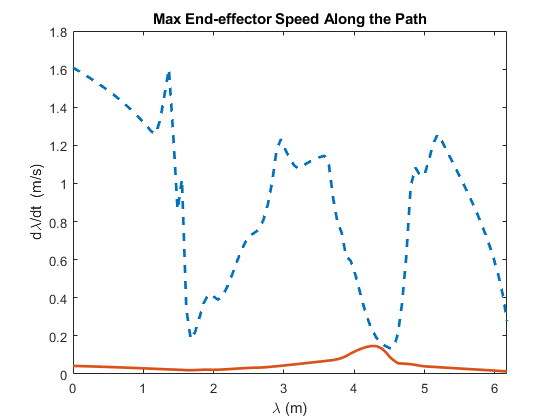

figure(12);plot(l(1:end-2),dldt1,'linewidth',2,'LineStyle',"--");
hold on;plot(l(1:end-2),ldot1(1:end-2),'linewidth',2);
hold off
xlabel('\lambda (m)')
ylabel('d\lambda/dt  (m/s)')
xlim([0,l(end-2)])
title('Max End-effector Speed Along the Path')

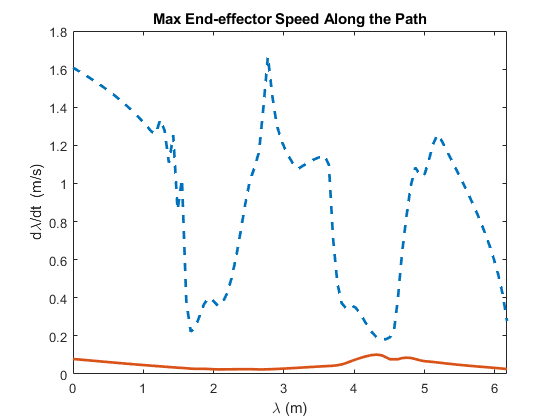

figure(13);plot(l(1:end-2),dldt2,'linewidth',2,'LineStyle',"--");
hold on;plot(l(1:end-2),ldot2(1:end-2),'linewidth',2);
hold off
xlabel('\lambda (m)')
ylabel('d\lambda/dt  (m/s)')
xlim([0,l(end-2)])
title('Max End-effector Speed Along the Path')